# Zombie Attack Model

Author: Darci Snowden

Jan 6, 2020

## Background

Zombies are attacking the world.  This code will help save mankind.

                            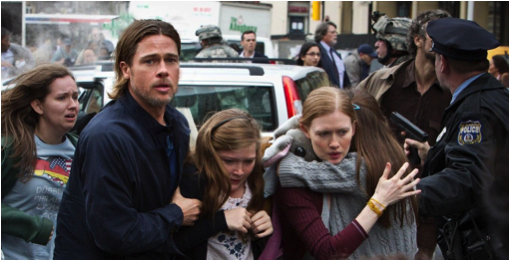

## Theory

The zombie attack can be quantified in terms of the number of humans (S), zombies (Z), and dead humans/zombies (R). The rate of change in the number of humans is determined by the birth rate ($\left.\Pi \right)$, normal death rate parameter ($\left.\delta \right)$, and zombie conversion rate parameter ($\left.\beta \right),$

                                                            $\frac{\textrm{dS}}{\textrm{dt}}=\Pi -\beta \;\textrm{SZ}-\delta \;S$.

The rate of change in the number of zombies is given by the production rate parameter ($\beta$), rate produced from the newly dead parameter ($\zeta$), and the kill rate parameter ($\alpha$),

                                                        $\frac{\;\textrm{dZ}}{\textrm{dt}}=\beta \;S\;Z+\zeta \;R-\alpha \;S\;Z$.

Finally, the rate of change in the number of dead things is determined by the number of humans that died of natural causes ($\left.\delta \right)$, killed zombies rate parameter ($\alpha$), and the rate parameter of the dead that are resurrected as zombies ($\zeta$),

                                                            $\frac{\textrm{dR}}{\textrm{dt}}=\delta \;S+\alpha \textrm{SZ}-\zeta R$.

To calculate the change in the numbers of humans, zombies, and dead things with time we must solve these equations simultanously.

## Results

First we will tell the computer the various rates.  You can adjust these later and observe how your changes affect the results.

Human birth rate in billions of humans per day:

clear all;

pi=0.;   

Zombie conversion rate per day:

beta = .0095;  

Natural-cause-death rate per day:

delta = 0.008; 

Zombie resurrection rate per day:

zeta = 0.002; 

Zombie kill rate per day:

alpha = 0.001; 

Next we have to tell the computer the number of people, dead things, and zombies at the beginning of our simulation.  We will base this on the US population only.

y0=[300 0 0];  %Array containing initial number of humans, zombies, dead

We also have to specify the interval of time we want to do the calculation for, we will choose 10 days.

tspan=[0 10];

We can use MATLAB's built-in ODE solver ODE23 to find the solution to the three differential equations.                                        

[t,y] = ode23(@(t,y) odefcn(t,y,pi,beta,delta,zeta,alpha), tspan, y0);

Finally we can make a nice visual of the results:

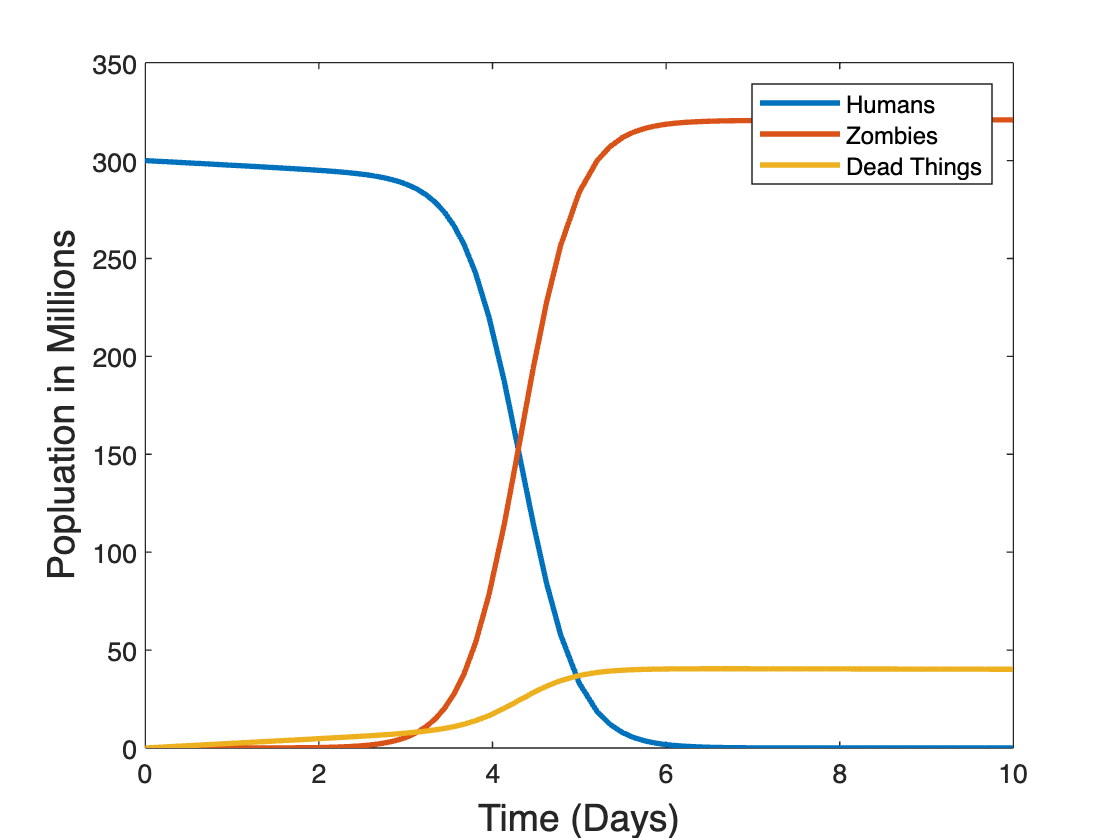

plot(t,y(:,1),t,y(:,2),t,y(:,3),'LineWidth',2.)
legend('Humans','Zombies','Dead Things')
xlabel('Time (Days)','FontSize',14.)
ylabel('Popluation in Millions','FontSize',14.)

We have to define the differential equations:

                                       $\frac{\textrm{dS}}{\textrm{dt}}=\Pi -\beta \;\textrm{SZ}-\delta \;S$.

                                       $\frac{\;\textrm{dZ}}{\textrm{dt}}=\beta \;S\;Z+\zeta \;R-\alpha \;S\;Z$.

                                       $\frac{\textrm{dR}}{\textrm{dt}}=\delta \;S+\alpha \textrm{SZ}-\zeta R$.

We will do this by writting a function that must be placed at the end of the program.

function dydt = odefcn(t,y,pi,beta,delta,zeta,alpha)
    dydt = zeros(3,1);
    dydt(1) = pi-beta*y(1)*y(2)-delta*y(1);
    dydt(2) = beta*y(1)*y(2)+zeta*y(3)+alpha*y(1)*y(2);
    dydt(3) = delta*y(1)+alpha*y(1)*y(2)-zeta*y(3);
end